## **이동평균 필터 (Moving Average Filter)**

**이동평균 필터**는 시간에 따라 변동하는 데이터를 부드럽게 하여 노이즈를 제거하고 신호의 **추세**를 파악하는 데 사용됩니다. 이 필터는 데이터에서 잡음을 제거하고, 보다 명확한 신호를 얻기 위해 널리 사용됩니다. 특히, 주식 시장, 센서 데이터 처리, 통신 신호 처리 등 다양한 분야에서 활용됩니다.

**1. ****이론적 배경**

이동평균 필터는 데이터를 일정 구간(window size) 동안 평균하여 변동성을 줄이는 기법입니다. 새로운 데이터가 추가되면 가장 오래된 데이터를 제외하고, 새 데이터를 반영하여 평균을 구합니다.

이동평균 필터는 크게 두 가지로 분류됩니다:

- **단순 이동평균 필터(SMA, Simple Moving Average)**: 모든 데이터를 동일하게 가중하여 평균을 계산합니다.

- **지수 이동평균 필터(EMA, Exponential Moving Average)**: 최근 데이터를 더 크게 가중하여 평균을 계산합니다.

**2. ****이동평균 필터의 수식****단순 이동평균(SMA)**

단순 이동평균은 일정한 구간 내에서 데이터를 평균하여 변동성을 줄입니다. nnn개의 데이터를 고려할 때, $k$번째 시점의 단순 이동평균은 다음과 같습니다.

$\bar{x}_k = \frac{x_{k-n+1} + x_{k-n+2} + \cdots + x_k}{n}$��

여기서:

- $n$은 창 크기 (moving window size)

- $x_k$는 시점 $k$에서의 데이터 값

- $\bar{x}_k$는 $k$시점에서의 이동평균 값

**지수 이동평균(EMA)**

지수 이동평균은 최근의 데이터에 더 큰 가중치를 부여하여 평균을 구합니다. EMA의 일반적인 수식은 다음과 같습니다.

$\text{EMA}_k = \alpha \cdot x_k + (1-\alpha) \cdot \text{EMA}_{k-1}$�

여기서:

- $\alpha$는 가중치 계수로, $\alpha = \frac{2}{n+1}$로 설정하는 것이 일반적입니다.

- $\text{EMA}_{k-1}$�은 이전 시점의 지수 이동평균 값

- $x_k$는 현재 시점의 데이터 값

EMA는 최근의 데이터를 더 중요하게 여기므로, 변화하는 신호를 더 빠르게 따라갈 수 있습니다.

**3. ****이동평균 필터의 종류와 장단점****단순 이동평균(SMA)**

- **장점**: 구현이 간단하고, 모든 데이터를 동일하게 처리하여 과거의 데이터도 반영할 수 있습니다.

- **단점**: 급격한 변화에 둔감하며, 전체 데이터를 동일한 가중치로 처리하기 때문에 최근 데이터의 중요도를 반영하기 어렵습니다.

**지수 이동평균(EMA)**

- **장점**: 최근 데이터를 더 중요하게 반영하여, 빠르게 변화하는 신호를 더 잘 반응할 수 있습니다.

- **단점**: 상대적으로 오래된 데이터를 덜 반영하기 때문에, 긴 시간에 대한 데이터 추세를 정확히 반영하지 못할 수 있습니다.

**4. ****이동평균 필터의 구체적인 적용 사례**

**1) ****주식 시장에서의 이동평균 필터**

주식 시장에서는 이동평균 필터가 주가의 **추세**를 파악하고, **매수/매도 신호**를 찾는 데 사용됩니다. 주가의 이동평균선을 계산하여, 주가가 이동평균선을 상향 돌파하면 매수 신호로, 하향 돌파하면 매도 신호로 해석할 수 있습니다.

- **단기 이동평균** (5일, 10일): 단기적인 주가 변화 추세를 파악하는 데 사용됩니다.

- **장기 이동평균** (50일, 200일): 장기적인 추세를 확인하고, 더 큰 변동성을 제거하는 데 유리합니다.

**2) ****센서 데이터 처리**

센서 데이터를 수집할 때, 측정 값에는 **잡음**이 포함될 수 있습니다. 이동평균 필터를 사용하여 잡음을 제거하고 부드럽고 신뢰성 있는 데이터를 얻을 수 있습니다.

예를 들어, **초음파 거리 측정기**에서 측정된 거리 값은 환경적인 요소에 따라 작은 변동이 있을 수 있습니다. 이러한 변동은 이동평균 필터를 적용하여 부드러운 신호로 바꿀 수 있습니다.

- **적용 사례**: 초음파 센서로 측정된 거리 데이터를 이동평균 필터를 적용하여 변동성을 줄이고, 더욱 정확한 거리 값을 얻을 수 있습니다.

**3) ****이미지 처리**

이미지에서 노이즈를 제거하고 부드러운 결과를 얻기 위해 이동평균 필터가 사용될 수 있습니다. **영상 처리**에서 이동평균 필터는 픽셀 단위로 노이즈를 줄이기 위한 중요한 기법입니다.

- **적용 사례**: 의료 영상에서 노이즈를 제거하고 진단에 필요한 영상을 부드럽게 만드는 데 사용됩니다. MRI 스캔이나 CT 스캔 데이터의 노이즈 제거에 필터를 적용할 수 있습니다.

**4) ****통신 신호 처리**

이동평균 필터는 통신에서 신호의 잡음을 제거하고 깨끗한 신호를 얻기 위해 사용됩니다. 통신 시스템에서 데이터 전송 중에 발생하는 잡음과 왜곡을 줄이는 역할을 합니다.

- **적용 사례**: 무선 통신 신호에서 이동평균 필터는 데이터 전송 중 발생하는 간섭과 잡음을 제거하고 신호의 정확도를 높이는 데 사용됩니다.

**5. ****이동평균 필터 적용 시 고려 사항**

- **데이터 개수 **$n$: 이동평균 필터에서 고려할 데이터 개수 $n$은 신호의 특성에 맞춰 조정해야 합니다. $n$이 크면 더 많은 데이터가 포함되어 **부드러운 신호**를 얻을 수 있지만, 반응이 느려질 수 있습니다. 반대로 $n$이 작으면 신호의 변화에 민감하지만, **잡음이 많이 남을 수** 있습니다.

- **실시간 데이터 처리**: 이동평균 필터는 **실시간 데이터 스트림**에서 잡음을 제거하고, 신호를 부드럽게 만드는 데 매우 유용합니다. 예를 들어, 센서 데이터를 수집할 때, 이동평균 필터를 적용하여 실시간으로 안정적인 데이터를 확보할 수 있습니다.

## **1. 초음파거리 측정 데이터에서의 적용**

**초음파 거리 측정 데이터**에서 노이즈를 제거하는 방법입니다. 이 코드는 앞서 설명한 대로 **측정된 거리 데이터**에 잡음이 섞여 있을 때, 이동평균 필터를 사용해 노이즈를 제거하고 부드러운 출력을 생성하는 과정입니다.

초음파 센서를 사용하여 물체와의 거리를 측정할 때, 잡음이나 환경적 요인에 의해 측정된 거리가 변동될 수 있습니다. 이동평균 필터를 적용하면 이러한 변동을 줄이고 더 정확한 거리를 측정할 수 있습니다.

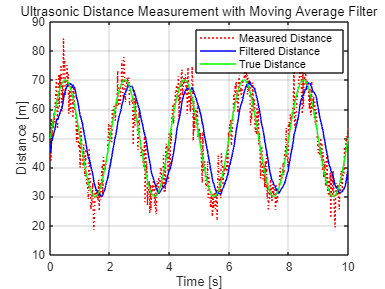

% 이동평균 필터를 적용한 초음파 거리 측정 데이터 처리

% 1. 가상의 초음파 거리 측정 데이터 생성
t = 0:0.02:10;  % 0.02초 간격으로 10초 동안의 데이터
true_distance = 50 + 20 * sin(2 * pi * 0.5 * t);  % 물체의 실제 거리 (사인파 형태로 변동)

% 측정값에 잡음 추가 (노이즈가 포함된 거리 측정값)
measured_distance = true_distance + 5 * randn(size(t));  % 노이즈 추가

% 2. 이동평균 필터 함수 구현
function avg_data = MovingAverageFilter(data, window_size)
    % window_size는 이동평균 필터의 데이터 개수 (n)
    avg_data = zeros(size(data));  % 필터링된 데이터를 저장할 배열 초기화
    for i = 1:length(data)
        if i < window_size
            avg_data(i) = mean(data(1:i));  % 초기 데이터는 누적 평균
        else
            avg_data(i) = mean(data(i-window_size+1:i));  % 이동평균 계산
        end
    end
end

% 3. 필터링 적용 (n 값에 따라 다르게 설정해 적용해보기)
window_size = 20;  % 이동평균을 계산할 데이터 개수 (n 값 설정)
filtered_distance = MovingAverageFilter(measured_distance, window_size);

% 4. 결과 시각화
figure;
plot(t, measured_distance, 'r:', 'DisplayName', 'Measured Distance');
hold on;
plot(t, filtered_distance, 'b-', 'DisplayName', 'Filtered Distance');
plot(t, true_distance, 'g-', 'DisplayName', 'True Distance');
legend('Location', 'Best');
title('Ultrasonic Distance Measurement with Moving Average Filter');
xlabel('Time [s]');
ylabel('Distance [m]');
grid on;

- **데이터 생성**:

- `true_distance`는 물체의 실제 거리 데이터를 시뮬레이션한 값입니다. 사인파 형태로 거리 변동을 모델링하였으며, 이는 50m를 중심으로 20m 범위에서 진동합니다.

- `measured_distance`는 실제 거리 데이터에 잡음을 추가한 값입니다. 이 잡음은 `randn` 함수를 이용해 가우시안 노이즈를 적용했습니다.

- **이동평균 필터 함수**:

- `MovingAverageFilter` 함수는 이동평균을 계산하는 함수로, 주어진 `window_size`(데이터 개수)만큼 데이터를 사용해 평균을 계산합니다.

- 처음에는 누적 평균을 사용하고, 이후부터는 이동 평균을 적용하여 데이터를 처리합니다.

- **필터 적용**:

- `window_size`는 이동평균 필터의 데이터 개수를 의미하며, 필터링의 민감도를 조정하는 데 사용됩니다. 이 값이 클수록 잡음 제거 효과가 커지지만 반응 속도는 느려집니다.

**결과 분석**

- **원본 측정값**은 노이즈가 포함되어 매우 불안정합니다.

- **이동평균 필터를 적용한 값**은 더 부드럽고, 신호의 잡음이 상당 부분 제거된 것을 확인할 수 있습니다.

- **실제 신호**와 필터링된 신호를 비교하면, 이동평균 필터가 노이즈를 얼마나 효과적으로 제거하는지 알 수 있습니다.

**데이터 개수의 효과**

`window_size`를 변경하여 필터의 민감도를 조정할 수 있습니다.

- **작은 window_size**: 신호가 빠르게 변하는 환경에서 유리하지만, 노이즈 제거 효과가 낮습니다.

- **큰 window_size**: 노이즈 제거 효과가 크지만, 신호의 변화에 민감하지 못해 반응이 느려집니다.

## 2. 주식시장 가격 변동성의 추세 분석 적용

주식 시장에서 **이동평균 필터**는 가격 변동성의 추세를 분석하는 데 자주 사용됩니다. 이동평균 필터는 **단기적 잡음을 제거**하고, 장기적인 가격 추세를 파악하는 데 유용합니다. 여기에서는 주식의 **단순 이동평균(SMA, Simple Moving Average)**을  주식의 가격 변동을 분석하는 사례를 설명하겠습니다. 

주식 시장에서 자주 사용되는 이동평균선은 **단기(5일)**와 **장기(20일)** 이동평균입니다. **단기 이동평균선**은 최근의 가격 변동을 더 민감하게 반영하고, **장기 이동평균선**은 주식의 전반적인 추세를 보여줍니다.

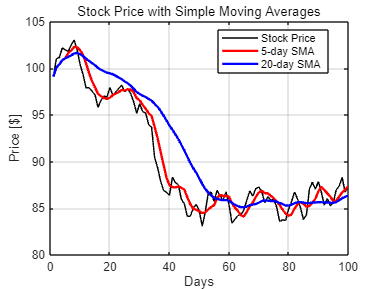

% 주식 시장에서 이동평균 필터를 적용한 사례

% 1. 가상의 주가 데이터 생성 (100일간)
days = 1:100;  % 100일간의 주식 데이터
stock_price = 100 + cumsum(randn(size(days)));  % 무작위 주가 데이터 생성

% 2. 단순 이동평균(SMA) 필터 함수 정의
function sma = SimpleMovingAverage(data, window_size)
    sma = zeros(size(data));  % 이동평균 값을 저장할 배열 초기화
    for i = 1:length(data)
        if i < window_size
            sma(i) = mean(data(1:i));  % 초기 구간은 누적 평균
        else
            sma(i) = mean(data(i-window_size+1:i));  % 이동평균 계산
        end
    end
end

% 3. 단기(5일) 및 장기(20일) 이동평균 계산
short_window = 5;  % 5일 이동평균
long_window = 20;  % 20일 이동평균

short_sma = SimpleMovingAverage(stock_price, short_window);  % 단기 이동평균
long_sma = SimpleMovingAverage(stock_price, long_window);  % 장기 이동평균

% 4. 결과 시각화
figure;
plot(days, stock_price, 'k-', 'DisplayName', 'Stock Price');
hold on;
plot(days, short_sma, 'r-', 'LineWidth', 2, 'DisplayName', '5-day SMA');
plot(days, long_sma, 'b-', 'LineWidth', 2, 'DisplayName', '20-day SMA');
legend('Location', 'Best');
title('Stock Price with Simple Moving Averages');
xlabel('Days');
ylabel('Price [$]');
grid on;

- **주가 데이터 생성**:

- `stock_price`는 100일 동안의 가상의 주가 데이터를 생성합니다. 이 데이터는 `randn` 함수를 사용해 무작위로 변동성을 추가하여 주가 변동을 모델링합니다.

- **이동평균 계산 함수**:

- `SimpleMovingAverage` 함수는 입력 데이터에 대해 지정된 **window_size**만큼의 기간을 기준으로 이동평균을 계산합니다.

- 처음 몇 개의 데이터는 누적 평균을 계산하고, 이후에는 이동평균을 사용합니다.

- **단기 및 장기 이동평균**:

- **단기 이동평균**: 5일 동안의 주가 변동을 반영하는 단기 이동평균을 계산합니다. 이는 최근의 변동을 빠르게 반영합니다.

- **장기 이동평균**: 20일 동안의 주가 변동을 반영하는 장기 이동평균을 계산합니다. 장기적인 추세를 더 명확하게 보여줍니다.

- **결과 시각화**:

- 주가 데이터를 검은 선으로 표시하고, 5일 이동평균은 빨간색 선으로, 20일 이동평균은 파란색 선으로 시각화합니다.

- 이를 통해 단기 및 장기 이동평균이 주가의 변동을 어떻게 반영하는지 확인할 수 있습니다.

**결과 분석**

- **단기 이동평균(5일)**: 주가의 최근 변동을 빠르게 반영합니다. 단기적인 추세 변동을 확인할 수 있으며, 주가의 최근 움직임에 민감하게 반응합니다.

- **장기 이동평균(20일)**: 주가의 전반적인 흐름을 보여줍니다. 노이즈가 줄어들고 장기적인 추세를 확인할 수 있습니다.

**매매 신호**

- 이동평균선은 매매 신호로도 자주 사용됩니다. 일반적으로 **단기 이동평균선**이 **장기 이동평균선**을 위로 교차할 때 **매수 신호**, 아래로 교차할 때 **매도 신호**로 해석됩니다. 이를 **골든 크로스**와 **데드 크로스**라고 부릅니다.

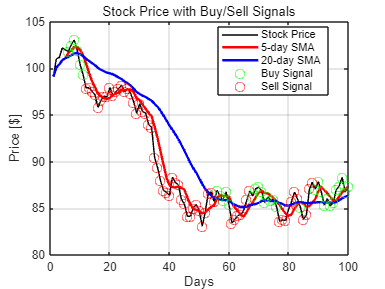

% 매매 신호 생성
buy_signal = (short_sma > long_sma);  % 단기 이동평균이 장기 이동평균을 넘을 때 매수 신호
sell_signal = (short_sma < long_sma);  % 단기 이동평균이 장기 이동평균 아래로 갈 때 매도 신호

% 매수/매도 신호 시각화
figure;
plot(days, stock_price, 'k-', 'DisplayName', 'Stock Price');
hold on;
plot(days, short_sma, 'r-', 'LineWidth', 2, 'DisplayName', '5-day SMA');
plot(days, long_sma, 'b-', 'LineWidth', 2, 'DisplayName', '20-day SMA');
plot(days(buy_signal), stock_price(buy_signal), 'go', 'MarkerSize', 8, 'DisplayName', 'Buy Signal');
plot(days(sell_signal), stock_price(sell_signal), 'ro', 'MarkerSize', 8, 'DisplayName', 'Sell Signal');
legend('Location', 'Best');
title('Stock Price with Buy/Sell Signals');
xlabel('Days');
ylabel('Price [$]');
grid on;

**매매 신호 설명**

- **매수 신호 (Buy Signal)**: 주가가 단기적으로 상승할 가능성을 시사합니다. 단기 이동평균선이 장기 이동평균선을 넘는 지점에 매수 신호가 표시됩니다.

- **매도 신호 (Sell Signal)**: 주가가 단기적으로 하락할 가능성을 시사합니다. 단기 이동평균선이 장기 이동평균선 아래로 내려가는 지점에 매도 신호가 표시됩니다.